# Lab 4 Robótica

### Allan Serrato, Juan Fernando Ramirez

### Módelo Cinemático PhantomX Nuevo:

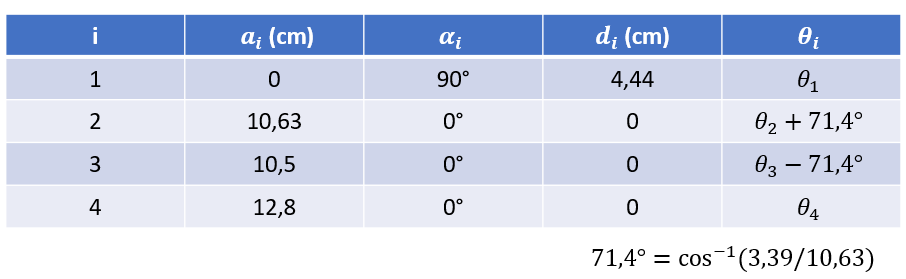

clear;
syms theta1 theta2 theta3 theta4
alpha2=acos(3.39/10.63) %radians

alpha2 = 1.2462

alpha2d=alpha2*180/pi %degrees

alpha2d = 71.4031

%MTH(ai,alphai,di,thetai,angleType0=rad)
% MTH de O1 respecto a O0
MTH01 = MTHDH(0,90,4.44,theta1,2) %degree and rad 

$$MTH01 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & \sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & 0\\ 0 & 1 & 0 & \frac{111}{25}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% MTH de O2 respecto a O1
MTH12 = MTHDH(10.63,0,0,theta2+alpha2,2)  %degree and rad 

$$MTH12 = \left(\begin{array}{cccc} \cos\left(\theta_{2}+\frac{2806234433688379}{2251799813685248}\right) & -\sin\left(\theta_{2}+\frac{2806234433688379}{2251799813685248}\right) & 0 & \frac{1063\,\cos\left(\theta_{2}+\frac{2806234433688379}{2251799813685248}\right)}{100}\\ \sin\left(\theta_{2}+\frac{2806234433688379}{2251799813685248}\right) & \cos\left(\theta_{2}+\frac{2806234433688379}{2251799813685248}\right) & 0 & \frac{1063\,\sin\left(\theta_{2}+\frac{2806234433688379}{2251799813685248}\right)}{100}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% MTH de O3 respecto a O2
MTH23 = MTHDH(10.5,0,0,theta3-alpha2,2)%degrees and rad

$$MTH23 = \left(\begin{array}{cccc} \cos\left(\theta_{3}-\frac{2806234433688379}{2251799813685248}\right) & -\sin\left(\theta_{3}-\frac{2806234433688379}{2251799813685248}\right) & 0 & \frac{21\,\cos\left(\theta_{3}-\frac{2806234433688379}{2251799813685248}\right)}{2}\\ \sin\left(\theta_{3}-\frac{2806234433688379}{2251799813685248}\right) & \cos\left(\theta_{3}-\frac{2806234433688379}{2251799813685248}\right) & 0 & \frac{21\,\sin\left(\theta_{3}-\frac{2806234433688379}{2251799813685248}\right)}{2}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

% MTH de O4 respecto a O3
MTH34 = MTHDH(12.8,0,0,theta4,2) %degree and rad

$$MTH34 = \left(\begin{array}{cccc} \cos\left(\theta_{4}\right) & -\sin\left(\theta_{4}\right) & 0 & \frac{64\,\cos\left(\theta_{4}\right)}{5}\\ \sin\left(\theta_{4}\right) & \cos\left(\theta_{4}\right) & 0 & \frac{64\,\sin\left(\theta_{4}\right)}{5}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

 Modelo geométrico directo (cinemática directa).

%MTH de O5 respecto a O0.
MTH04=MTH01*MTH12*MTH23*MTH34

### Gráfica del modelo con el Toolbox de PeterCorke:

%MATRIZ DH 
% columnas en orden: thetai, di, ai, alphai
%cada fila es un qi.
q1=[0 4.44 0 pi/2];
q2=[alpha2 0 10.63 0];
q3=[-alpha2 0 10.5 0];
q4=[0 0 12.8 0];
DH1 = [q1;q2;q3;q4]

DH1 =          0    4.4400         0    1.5708
    1.2462         0   10.6300         0
   -1.2462         0   10.5000         0
         0         0   12.8000         0


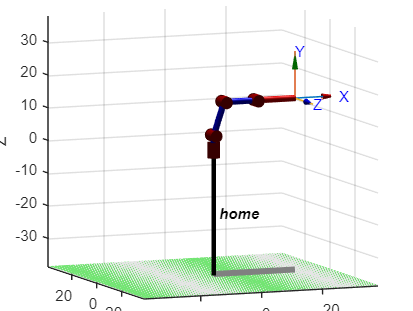

robot1 = SerialLink(DH1);

%plotear configuracion qz=[0,0,0,0]
robot1.name = 'home';
figure()
title('Home Peter Corke')
%toca agregar manualmente los offset de theta2 y theta3.
robot1.plot([0,alpha2,-alpha2,0])

view([-22.3 7.9])

Esra configuración Home es la que el PhantomX adopta cuando se le envia la pose [0,0,0,0] en el script de python.

### Diferentes Configuraciones del Robot Probadas:

En este módelo de matlab no se tiene en cuenta el ángulo que controla la apertura del gripper del PhantomX, por lo que se evaluaran los primeros cuatro ángulos de las posturas planteadas en la gúia.

- Configuración 2: [-20°,20°,-20°,20°]

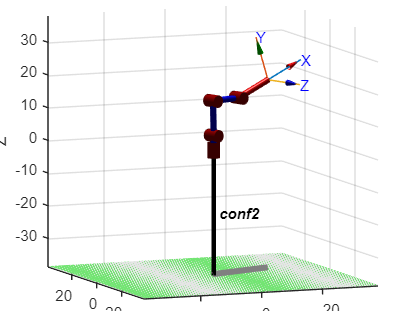

%configuracion q2=[20°,20°,-20°,20°]
robot1.name = 'conf2';
figure()
title('conf2 Peter Corke')
robot1.plot([deg2rad(20),deg2rad(20)+alpha2,deg2rad(-20)-alpha2,deg2rad(20)])

view([-22.3 7.9])

- Configuración 3: [30°,-30°,30°,-30°]

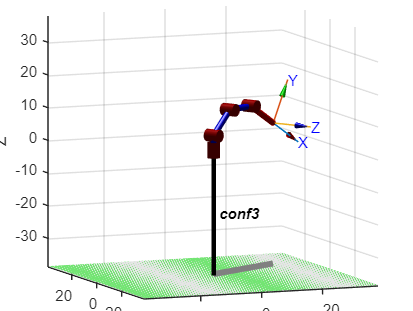

%configuracion q3=[30°,-30°,30°,-30°]
robot1.name = 'conf3';
figure()
title('conf3 Peter Corke')
robot1.plot([deg2rad(30),deg2rad(-30)+alpha2,deg2rad(30)-alpha2,deg2rad(-30)])

view([-22.3 7.9])

- Configuración 4: [-90°,15°,-55°,17°]

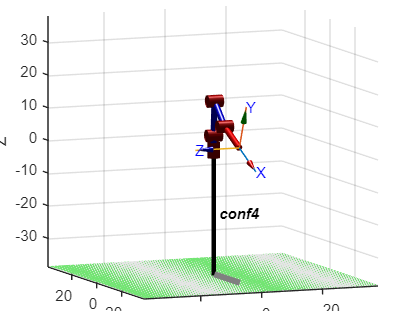

%configuracion q4=[-90°,15°,-55°,17°]
robot1.name = 'conf4';
figure()
title('conf4 Peter Corke')
robot1.plot([deg2rad(-90),deg2rad(15)+alpha2,deg2rad(-55)-alpha2,deg2rad(17)])

view([-22.3 7.9])

- Configuración 5: [90°,45°,-55°,45°]

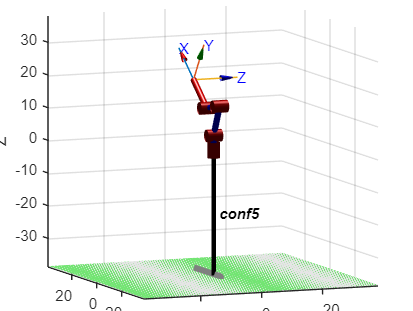

%configuracion q5=[90°,45°,-55°,45°]
robot1.name = 'conf5';
figure()
title('conf5 Peter Corke')
robot1.plot([deg2rad(90),deg2rad(45)+alpha2,deg2rad(-55)-alpha2,deg2rad(45)])

view([-22.3 7.9])

function [H] = MTHDH(ai,alphai,di,thetai,angleType)
%Hecho por Andrés Felipe Forero Salas
%Función para calcular la Matriz de Transformación Homogénea
%dados los parámetros DHstd en diferentes posibles sistemas
%numéricos
%MTH para DH desde el marco i-1 al marco i.
    if angleType == 0 %rad
        H = [cos(thetai) -sin(thetai)*cos(alphai) sin(thetai)*sin(alphai) ai*cos(thetai);sin(thetai) cos(thetai)*cos(alphai) -cos(thetai)*sin(alphai) ai*sin(thetai); 0 sin(alphai) cos(alphai) di; 0 0 0 1];
    elseif angleType == 1 %degrees
        H = [cosd(thetai) -sind(thetai)*cosd(alphai) sind(thetai)*sind(alphai) ai*cosd(thetai);sind(thetai) cosd(thetai)*cosd(alphai) -cosd(thetai)*sind(alphai) ai*sind(thetai); 0 sind(alphai) cosd(alphai) di; 0 0 0 1];
    elseif angleType == 2 %alphai en degree,thetai en rad, 
        H = [cos(thetai) -sin(thetai)*cosd(alphai) sin(thetai)*sind(alphai) ai*cos(thetai);sin(thetai) cos(thetai)*cosd(alphai) -cos(thetai)*sind(alphai) ai*sin(thetai); 0 sind(alphai) cosd(alphai) di; 0 0 0 1];
    elseif angleType == 3 %alphai en rad,thetai en degree,
        H = [cosd(thetai) -sind(thetai)*cos(alphai) sind(thetai)*sin(alphai) ai*cosd(thetai);sind(thetai) cosd(thetai)*cos(alphai) -cosd(thetai)*sin(alphai) ai*sind(thetai); 0 sin(alphai) cos(alphai) di; 0 0 0 1];
    end
end